function tau = computeTau(signal)
    x_mutual = mutual(signal, 32, 20); % Ensure mutual is thread-safe
    [~, min_idx] = findpeaks(-x_mutual);
    if isempty(min_idx)
        tau = 20; % Default to max if no clear minimum
    else
        tau = min_idx(1); % First minimum
    end
end

function embedding = computeEmbedding(signal, tau) % Fixed typo
    fnn = false_nearest(signal, 1, 20, tau, 10); % Ensure false_nearest is thread-safe
    embedding = 20; % Default
    for j = 1:20
        if (fnn(j, 2) <= 0.01 && ~isnan(fnn(j, 2)))
            embedding = j;
            break;
        end
    end
end

y = linspace(0, 5, 100);  % 100 points in the interval [0, 5]
x = sin(2 * pi * y)+0.0001; %sin

function plotRM(RM)
    h3 = figure('Name', 'Raw Recurrence Matrix', 'Position', [100, 100, 400, 400], 'Visible', 'on');
    clf;
    imagesc(RM);
    colormap('hot');
    colorbar;
    axis square;
    title('Raw Recurrence Matrix');
    xlabel('Time Index');
    ylabel('Time Index');
    drawnow;
    fprintf('Figure 3 (Raw RM) created.\n');
end

function RM_tresh = treshold_RM(RM)
    RM_flat = RM(:);
    p_min = prctile(RM_flat,5);
    p_max = prctile(RM_flat,90);
    RM_norm = (RM-p_min)/(p_max-p_min);
    RM_norm = max(0,min(1,RM_norm));
    RM_flat = RM_norm(:);

    std_flat = 1.5*mad(RM_flat);
    RM_tresh = RM < 1.25*std_flat;
end


tau=computeTau(x);
embedding = computeEmbedding(x, tau);

Start for dimension=1
Found 4 up to epsilon=1.999748e-03
Found 6 up to epsilon=2.828071e-03
Found 8 up to epsilon=3.999497e-03
Found 12 up to epsilon=5.656142e-03
Found 18 up to epsilon=7.998993e-03
Found 24 up to epsilon=1.131228e-02
Found 34 up to epsilon=1.599799e-02
Found 52 up to epsilon=2.262457e-02
Found 99 up to epsilon=3.199597e-02
Start for dimension=2
Found 0 up to epsilon=1.999748e-03
Found 0 up to epsilon=2.828071e-03
Found 0 up to epsilon=3.999497e-03
Found 0 up to epsilon=5.656142e-03
Found 0 up to epsilon=7.998993e-03
Found 0 up to epsilon=1.131228e-02
Found 0 up to epsilon=1.599799e-02
Found 0 up to epsilon=2.262457e-02
Found 0 up to epsilon=3.199597e-02
Found 2 up to epsilon=4.524914e-02
Found 94 up to epsilon=6.399194e-02
Start for dimension=3
Found 0 up to epsilon=4.524914e-02
Found 89 up to epsilon=6.399194e-02
Start for dimension=4
Found 84 up to epsilon=6.399194e-02
Start for dimension=5
Found 79 up to epsilon=6.399194e-02
Start for dimension=6
Found 74 up to eps

RM = computeRM_blockedkronecker_nonsymmetric(x,10,1,50,2);

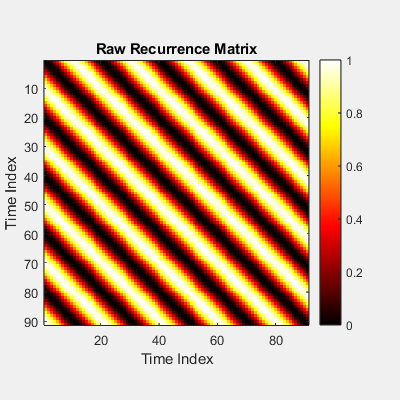

Figure 3 (Raw RM) created.


plotRM(RM);

RM_thresh = treshold_RM(RM);

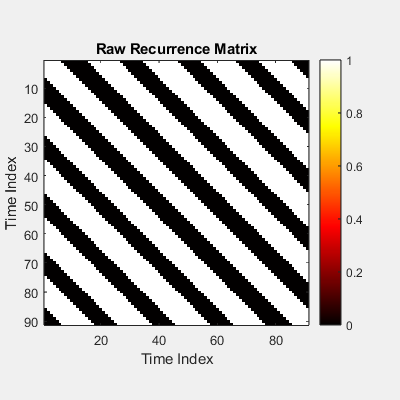

Figure 3 (Raw RM) created.


plotRM(RM_thresh);

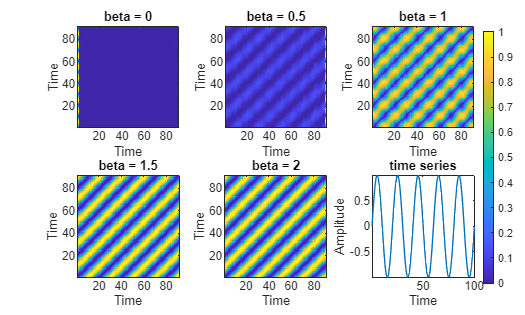

plot_betas(x,10,1);